# ME390 Path Planning

## Initialization

clear
close all
clc

## Map Generation

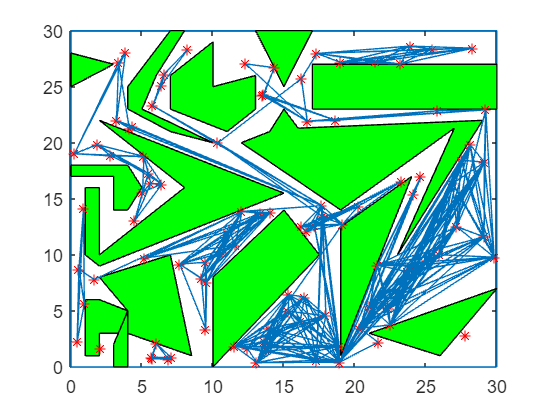

% number of nodes 
ns=100;
map=map_definition();
% 
% generate random nodes
[map, nodelocation]= generate_node(map,ns);


% create undirected graph and its edges
[undirectedGraph,unedges]=generate_undirected_graph(map,nodelocation);

## Start & End Point Def

% define start and end point of simulation
startp=[2, 29];
endp=[29, 0.5];

% add start and end location as a new 2 nodes in undirected map.
% n+1 th node is start point, n+2th node is end point
[extungraph,exnodelocation,exunedges ]=addstartendpoint2ungraph(map,undirectedGraph,nodelocation,unedges,startp,endp);
exundnodIndex=[1:ns+2];
snodeund=ns+1;
enodeund=ns+2;

## Path Planning Main

### dijkstra

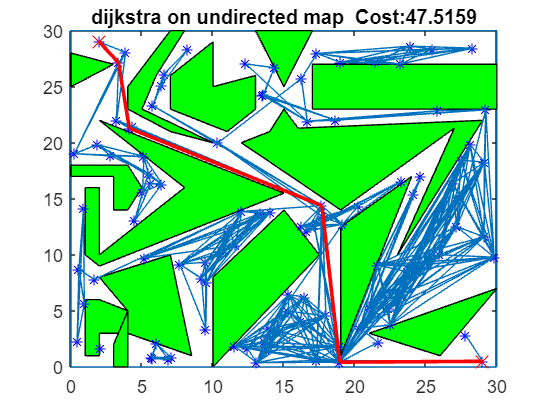

% optimal path with dijkstra on un-directional map
[Route, Cost] = dijkstra(extungraph,exnodelocation,snodeund);
rt=Route{enodeund};

dijkstra_route=exnodelocation(rt,:);
cost=pathcost(dijkstra_route);
drawRoute('dijkstra on undirected map',snodeund,enodeund,exnodelocation,exundnodIndex,exunedges,rt,cost);

### A*

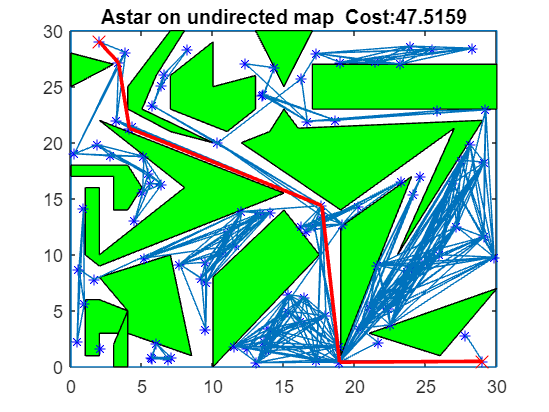

% optimal path with astar on un-directional map
[Route] = astar(extungraph,exnodelocation,snodeund,enodeund);
astar_route=exnodelocation(Route,:);
cost=pathcost(astar_route);
drawRoute('Astar on undirected map',snodeund,enodeund,exnodelocation,exundnodIndex,exunedges,Route,cost);

### Dynamic Programming

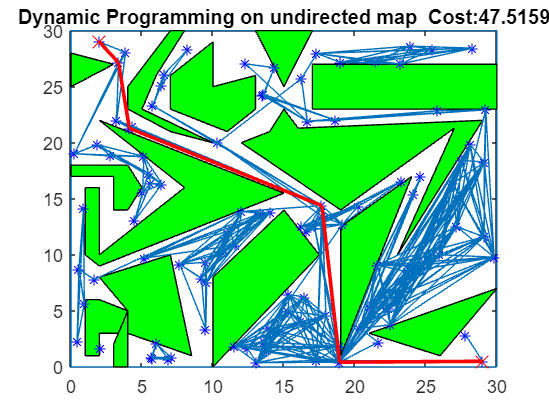

% optimal path with dynamic programming on un-directional map
[parent, Route]=dynamicpathplanning(extungraph,exnodelocation,exundnodIndex,snodeund,enodeund);
dpundirected_route=exnodelocation(Route,:);
cost=pathcost(dpundirected_route);
drawRoute('Dynamic Programming on undirected map',snodeund,enodeund,exnodelocation,exundnodIndex,exunedges,Route,cost);

## Motion Generation & RealTime Analysis

% Motion generation and realtime values


Yuanshao Yang, UMich ME

2024